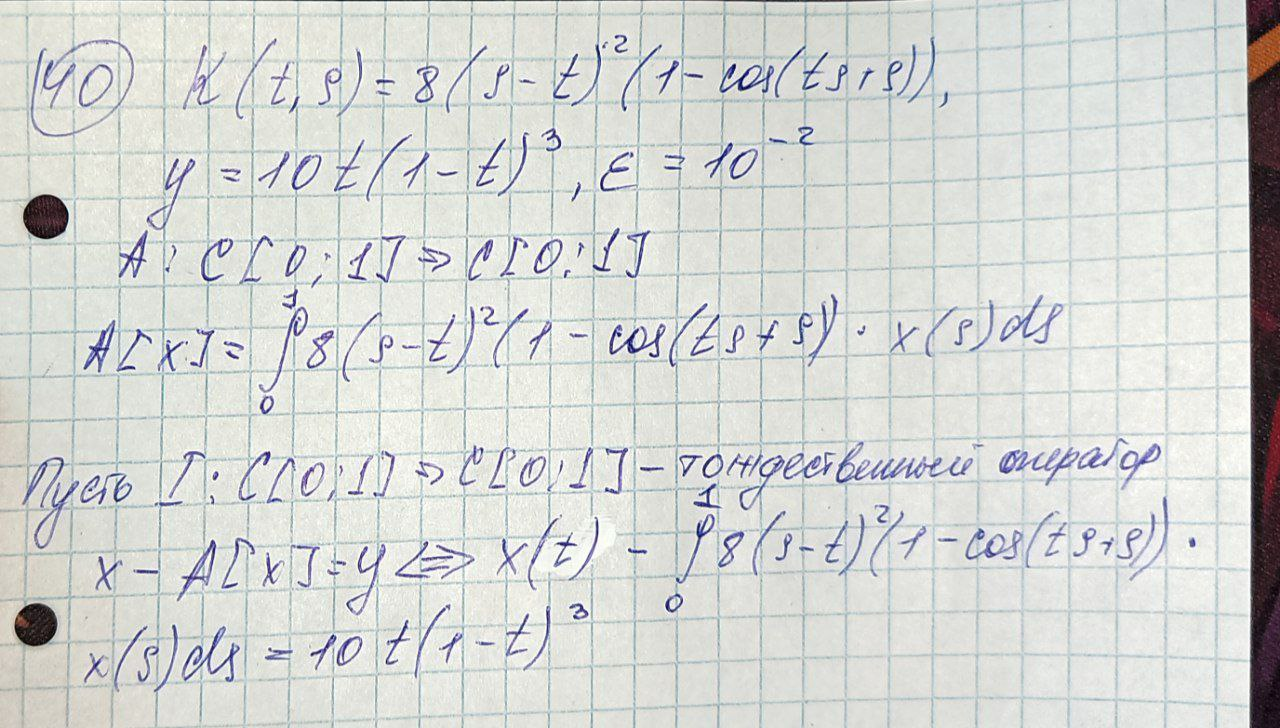

По сути, подсчет ||A|| сводится к подсчету максимума интеграла от ядра K

K = @(t,s) 8*(s - t).^2 .* (1 - cos(t.*s + s)); %ядро
T = linspace(0,1,100);       % сетки для подсчета
S = linspace(0,1,100);       
norm = zeros(size(T));      
for i = 1:length(T)
    t_i = T(i);
    integrand = abs( K(t_i, S) );    % вычисляем |K(t, s)| для всех s
    norm(i) = trapz( S, integrand );
end
norm_m = max(norm);     % ищем максимум по всей сетке
fprintf('||A||<=  %f\n', norm_m);

||A||<=  0.753717


Так как ||A||<1, то оператор I-A неприрывно обратим(ч.т.д) и для нормы обратного оператора имеется следующая оценка

norm_obr = 1/(1-norm_m);
fprintf('||(I - A)^-1|| <= %f\n', norm_obr);

||(I - A)^-1|| <= 4.060377


Раскладываем ядро в ряд Тейлора (n=10)

syms t s
f_sym = K(t, s); %переводим из анонимной функции в символьную, поскольку taylor() применим только к символьным
K_sym = taylor(f_sym, [t, s], [0, 0], 'Order', 11); 
disp(K_sym);

$$-\frac{s^{10}}{5040}+\frac{s^{9}\,t}{2520}+\frac{839\,s^{8}\,t^{2}}{5040}+\frac{s^{8}\,t}{15}+\frac{s^{8}}{90}-\frac{s^{7}\,t^{3}}{3}-\frac{2\,s^{7}\,t^{2}}{15}-\frac{s^{7}\,t}{45}-\frac{s^{6}\,t^{4}}{6}-\frac{19\,s^{6}\,t^{3}}{15}-\frac{179\,s^{6}\,t^{2}}{90}-\frac{4\,s^{6}\,t}{3}-\frac{s^{6}}{3}+\frac{2\,s^{5}\,t^{5}}{3}+\frac{8\,s^{5}\,t^{4}}{3}+4\,s^{5}\,t^{3}+\frac{8\,s^{5}\,t^{2}}{3}+\frac{2\,s^{5}\,t}{3}-\frac{s^{4}\,t^{6}}{3}-\frac{4\,s^{4}\,t^{5}}{3}-2\,s^{4}\,t^{4}-\frac{4\,s^{4}\,t^{3}}{3}+\frac{11\,s^{4}\,t^{2}}{3}+8\,s^{4}\,t+4\,s^{4}-8\,s^{3}\,t^{3}-16\,s^{3}\,t^{2}-8\,s^{3}\,t+4\,s^{2}\,t^{4}+8\,s^{2}\,t^{3}+4\,s^{2}\,t^{2}$$

Решаем уравнение МПИ

t_old = 1;

for n = 1:11
    integrand = K_sym * subs(t_old, t, s);
    integral_val = int(integrand, s, 0, 1);
    t_new = integral_val + 10*t*(1-t)^3;
    t_new = simplify(t_new);
    t_old = t_new;
end
%disp('Результат x_6(t) методом МПИ:');
%disp(t_new);

Сейчас в t_new храниться приближенное решение

Далее вычисляем ||(I-A)[x*]-y||

x_anon = matlabFunction(t_new, 'Vars', t);%переводим функцию в анонимную
x = x_anon(T);
[TT_full, SS_full] = meshgrid(T, S);
K_vals = K(TT_full, SS_full); 
Ax_vals = zeros(size(T));
for j = 1:length(T)
    integrand_full = K_vals(:, j) .* x(:);
    Ax_vals(j) = trapz(S, integrand_full);
end
y_vals = 10 .* T .* (1 - T) .^3;
neuv = x - Ax_vals - y_vals;
norm_neuv = max(abs(neuv));
fprintf('|| (I - A)[x*] - y ||_{C[0,1]} = %.6f\n', norm_neuv);

|| (I - A)[x*] - y ||_{C[0,1]} = 0.000624


Использую оценку нормы обратного оператора, оцениваем ||x*-x||

norm_x = norm_neuv * norm_obr;
fprintf('||x*-x|| <= %.8f\n', norm_x);

||x*-x|| <= 0.00253193


Проверяем точность

disp( string(norm_x < 1e-2) );

true


=> получена нужная точность

Графики

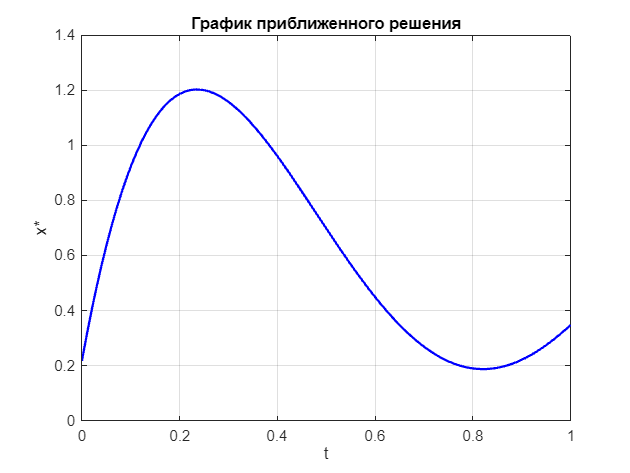

figure;
plot(T, x, 'b-', 'LineWidth', 1.5);
xlabel('t', 'Interpreter','none');
ylabel('x*', 'Interpreter','none');
title('График приближенного решения', 'Interpreter','none');
grid on;

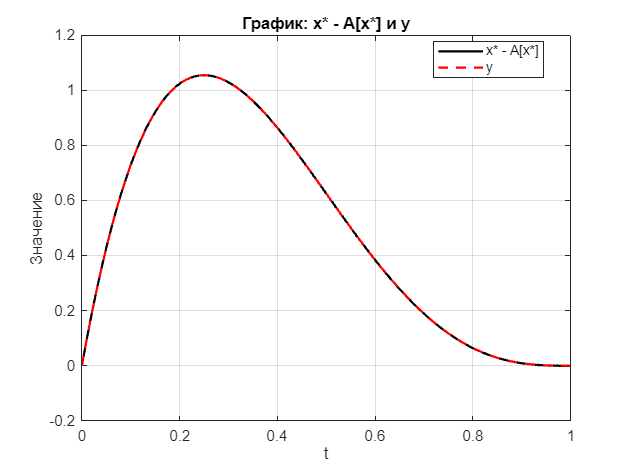

plot2=x - Ax_vals;
figure;
plot(T, plot2, 'k-', 'LineWidth', 1.5); hold on;
plot(T, y_vals,   'r--', 'LineWidth', 1.5);
xlabel('t', 'Interpreter','none');
ylabel('Значение', 'Interpreter','none');
title('График: x* - A[x*] и y', 'Interpreter','none');
legend('x* - A[x*]','y','Location','best','Interpreter','none');
grid on;
hold off;